# Implementing vehicle dynamic model and waypoints generator algorithm into MOBATSim

This document introduces the vehicle dynamic model's implementation, along with the waypoints generator and pure pursuit controller into MOBATSim. This implementation aims to make MOBATSim more practical by enabling lateral movement control. The movement of a vehicle would be more realistic, and this gives MOBATSim more extendibility for further development.

## Changes in prepare_simulator.m

The prepare_simulator.m file loads all pre-defined driving scenarios and vehicle parameters required for simulation. 

prepare_simulator;

For convenience consideration, several new codes were added:

line3

clc;% clear Command Window

line76

figure('Name','waypoints');
hold on

This is for visualizing simulation results. It will dramatically slow down the simulation speed. So comment this out if you don't want to debug the code.

line80

v2_Xi = Map.waypoints(Vehicle2.pathInfo.startingPoint,1);
v2_Yi = -Map.waypoints(Vehicle2.pathInfo.startingPoint,3);

These two parameters are the initial position of Vehicle2. The vehicle position in the "Vehicle" class is in [x y z] format, which needs to be transferred to [x z y] to be used in the vehicle dynamic model. Furthermore, the z-axis in the "Vehicle" class needs to be reversed to plot correctly. The transformation between different coordinate systems will be explained later.

## Changes in Vehicle.m

We create a new variable to store the next ten reference waypoints for each vehicle :

obj.dynamics.reference_waypoints = [0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;0 0 0;];

Differential to the original coordinate, the reference waypoints are in [x z y] format corresponding to the following local coordinate:

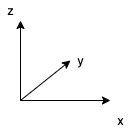

Mind that all new variables with 'local' prefix are in local coordinate. In order to transform positions in MOBATSim coordinate to local coordinate, the following process should proceed:


$$\left[ \begin{array}{c}
x \\
z\\
y 
\end{array}
\right ]_{local}=
\left[ \begin{array}{c}
x \\
y\\
-z 
\end{array}
\right ]_{m}$$


where subscript 'local' and 'm' represent local coordinate and MOBATSim coordinate.

## Changes in MOBATSim.slx

All changes are only in vehicle 2:

- Replace Matlab system 'VehicleKinematics' with 'VehicleKinematic_Qihang'. Detail information will be explained later.

- Add 'Pure Pursuit' and 'Wheel Steering Angle Formulation' blocks for pure pursuit control.

- Add the 'Vehicle Body 3DOF Dual Track' block to simulate a real vehicle's movement. Inputs of this block are wheel steering angle and reference speed. Outputs are vehicle information such as position, steering angle, and speed. These data are then used in 'VehicleKinematic_Qihang'.

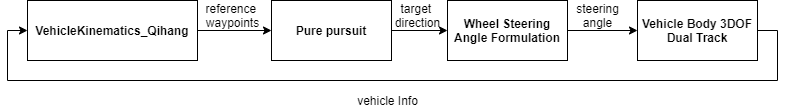

Except for the 'VehicleKinematic_Qihang' Matlab system, the other three blocks are pre-defined blocks from the Matlab toolbox. Detailed information about these blocks is available in Matlab documentation.

## Changes in 'VehicleKinematic_Qihang'

Compared with the original 'VehicleKinematics' block, several changes were made:

- Vehicle Info from 'Vehicle Body 3DOF Dual Track' block added to inputs of the block.

- A new algorithm for waypoints generation is developed.

- Reference waypoints are generated and output.

Following chart shows the control logic of this block:

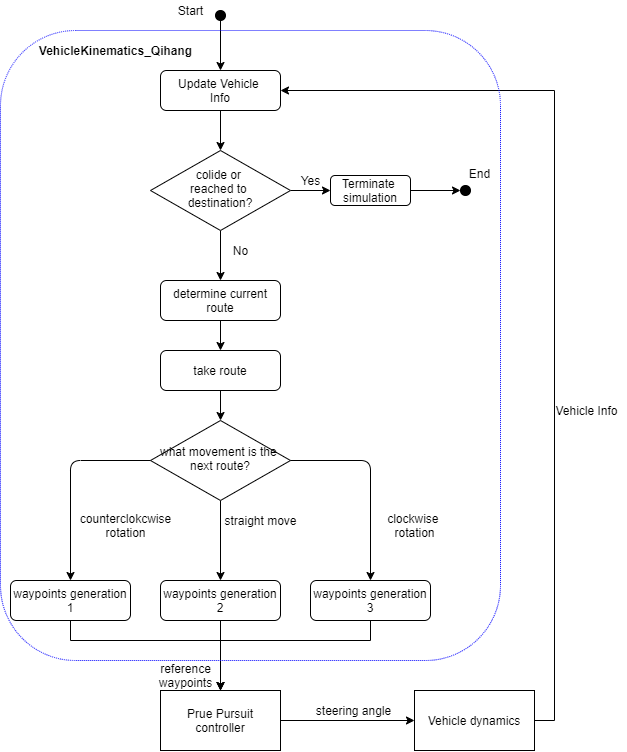

Breakpoint at line 44 is recommended to be added if the user wants to debug. Right after stepImpl function:

function [position, rotation, reference_waypoints] = stepImpl(obj,v_pos,drivingMode)

Vehicle Infos that are required in this block are the vehicle's position, orientation, and speed. Input is a bus signal v_pos = [X Y psi speed].

Firstly, vehicle Infos were updated, and values were stored in obj.Vehicle.

obj.vehicle.dynamics.position = [v_pos(1) 0 -v_pos(2)];%transfer from local coordinate to MOBATSim coordinate
obj.vehicle.dynamics.speed = v_pos(4);
obj.vehicle.dynamics.cornering.angles = v_pos(3);

Same with original codes, vehicle status was checked:

if obj.vehicle.status.collided
    %Output 1: Position of the vehicle
    position= obj.vehicle.dynamics.position;
    %Output 2: Rotation angle of the vehicle
    rotation= obj.vehicle.dynamics.orientation;
    %Output 3: reference waypoints
    reference_waypoints = obj.vehicle.dynamics.reference_waypoints(:,[1 3]);
    return;
end

The same with the original codes, the vehicle's status was checked, and the route was set. The user can put a breakpoint at line 113 to skip the route generation function.

When a route is generated, the vehicle should execute its next movement. This is realized in the nextMove function.

function nextMove(obj, car)

When a route is generated, the vehicle should execute its next movement. The nextMove function is called up to determine how the vehicle's next movement is. The takeRoute function is then called up to execute this movement.

function takeRoute(obj,car,refRoute)

If the vehicle should execute a straight movement, the moveto function will be called up at line 164:

if RotationVector(1) == 0 %Straight motion
    obj.moveto(car,refRoute(2,:));

As a recommendation, breakpoint at line 181 should be added to dive deeper into the moveto function.

function moveto(obj ,car,Destination)

The moveto function will call up the generate_straight_move_WPs function to generate reference waypoints for straight movement. The generate_straight_move_WPs function contains a newly designed algorithm. This function is where most changes were made. Breakpoint at line 262 was added to explain the algorithm step by step.

function generate_straight_move_WPs(obj, car,Destination)

### Generate reference waypoints for straight move

Following figure shows how the reference waypoints for staight move are generated: 

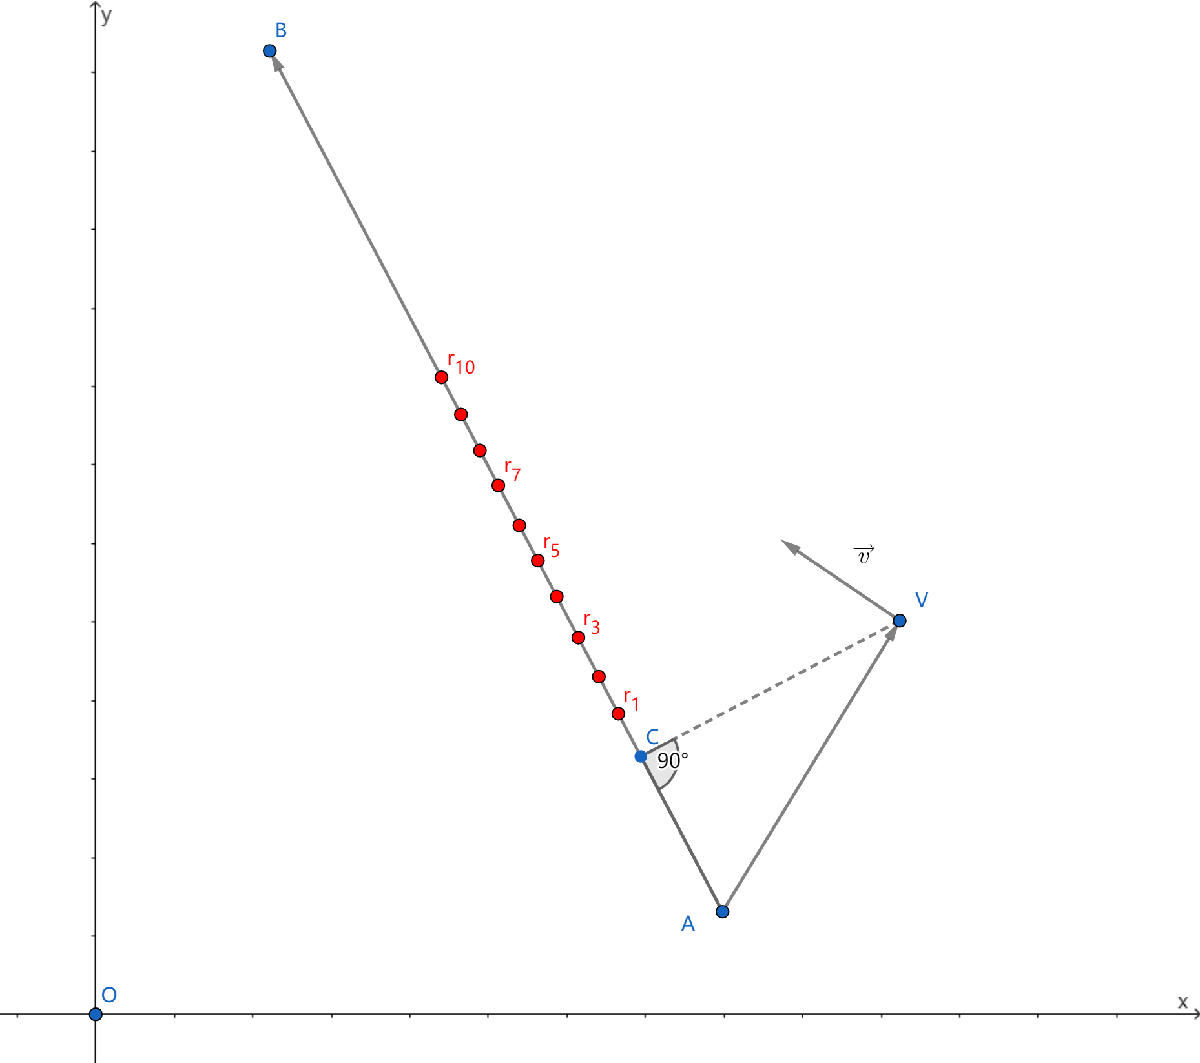

where,

$A$: the starting point for the current route

$B$: the destination point. 

$V$: Vehicle's current position

$O$: Coordinate origin

$r$: reference waypoints

$\overrightarrow{v}$: speed vector of the vehicle

The destination point $B
$ and route vector$\overrightarrow{AB}$ are transferred from MOBATSim coordinate into local coordinate.

local_route_Vector_i $\overrightarrow{ab}$ is the unit vector of $\overrightarrow{AB}$ in local coordinate.


$$\overrightarrow{ab}=\frac{\overrightarrow{AB}}{|\overrightarrow{AB}|}$$


local_destination = Destination.*[1 1 -1];
route_Vector = car.pathInfo.currentTrajectory(2,:)-car.pathInfo.currentTrajectory(1,:);
local_route_Vector_i = route_Vector/norm(route_Vector).*[1 1 -1];

pos_Vector $\overrightarrow{AV}$is from the route starting point to the vehicle's current position.

pos_Vector = car.dynamics.position-car.pathInfo.currentTrajectory(1,:);
local_pos_Vector = pos_Vector.*[1 1 -1];

setoff_distance $|\overrightarrow{AC}|$is the longitudinal traveled distance of the vehicle mapped to the current route.


$$|\overrightarrow{AC}|=\overrightarrow{AV}\cdot\overrightarrow{ab}$$


setoff_distance = dot(local_pos_Vector,local_route_Vector_i);

local_WP_start_point $C$ is the point where the reference waypoints start.


$$\overrightarrow{OC}=\overrightarrow{OA}+\overrightarrow{AC}$$


local_WP_start_point = (setoff_distance*local_route_Vector_i+car.pathInfo.currentTrajectory(1,:).*[1 1 -1]);

The next ten reference waypoints were generated with a step length $l_{step}=0.3\overrightarrow{v}\cdot\overrightarrow{ab}$. 


$$\overrightarrow{r_i}=\overrightarrow{OC}+i\cdot l_{step},    \qquad i =1,2,...10$$


And if a reference point exceeds the destination point, the destination point will be used as the reference point.

for i = 1:1:length(car.dynamics.reference_waypoints)
    car.dynamics.reference_waypoints(i,:) = local_WP_start_point+norm(min(i*(car.dynamics.speed*dot([cos(car.dynamics.cornering.angles) 0 sin(car.dynamics.cornering.angles)],local_route_Vector_i)*0.01*30),norm(local_destination - local_WP_start_point)))*local_route_Vector_i;
    %30 is the factor that adjust the reference WP step length
end

### Check if the vehicle has reached its destination.

After waypoints are generated, the moveto function will check if the vehicle has reached its destination to determine if another route should be taken.

To minimize the control error's influence and increase the system's redundancy, we consider the vehicle has reached its destination when the distance between the vehicle's current position and the destination point is smaller than 2 meters. 

if  norm(car.dynamics.position-Destination)<2
    %car.dynamics.position = Destination; %Because of the rounding errors may be modified later
    car.pathInfo.routeCompleted=true;
    car.pathInfo.lastWaypoint = car.map.get_waypoint_from_coordinates (Destination);

### generate waypoints for counterclockwise rotation

Like straight move, the moveto function will call up the rotate_counterclockwise function when the vehicle's next movement is a left turn in its Freenet coordinate.

The user can add a breakpoint at line 169 to check the condition.

if car.pathInfo.currentTrajectory(4,:) == -ones(1,3) % -1 means turn counterclockwise
    obj.rotate_counterclockwise(car, rotation_point,rotation_angle,P_final);

The rotate_counterclockwise function will call up the generate_rotate_counterclockwise_WPs function to generate referecne waypoints.

The user can add a breakpoint at line 347 to check the detailed algorithm.

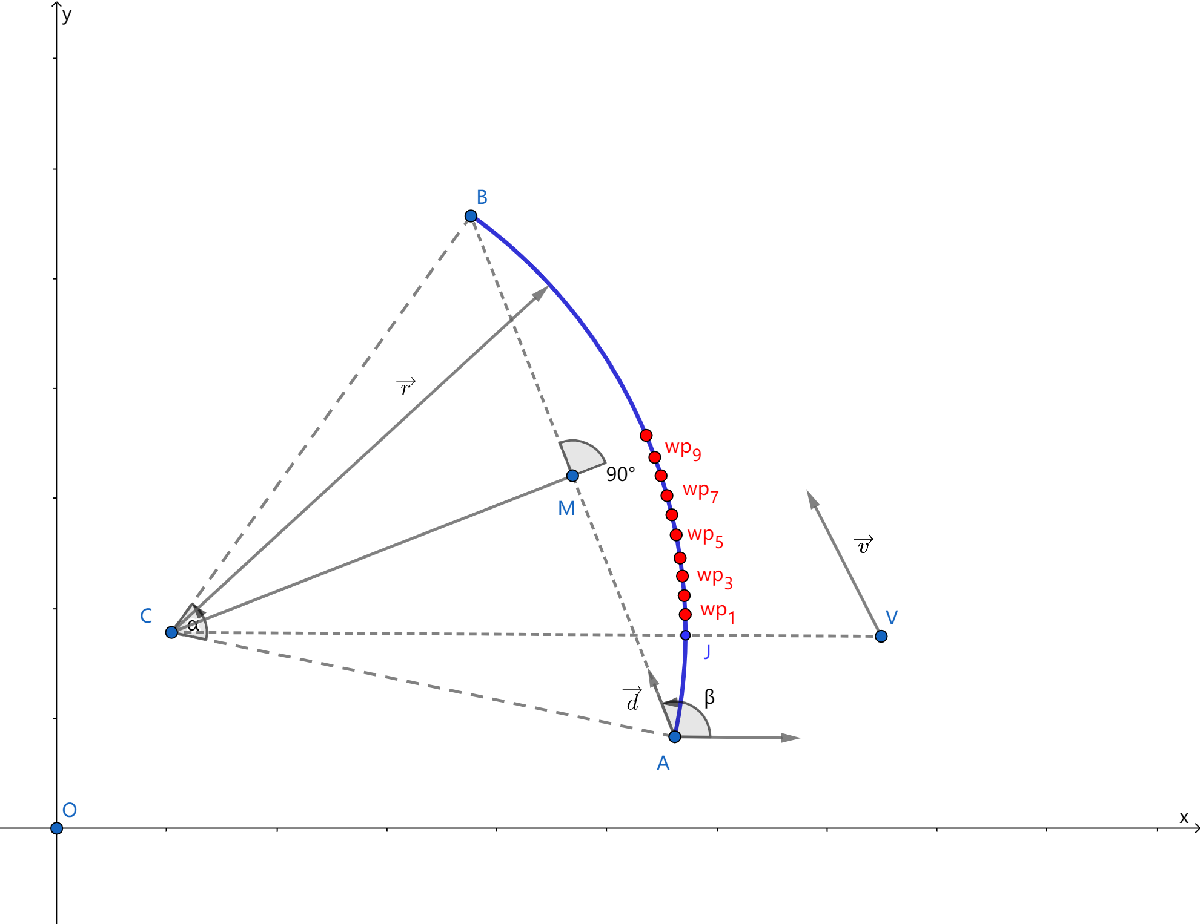

where,

$A$: the starting point for the current route

$B$: the destination point. 

$C$: Center of the rotation

$V$: Vehicle's current position

$O$: Coordinate origin

$M
$: the crosspoint of $AB
$ and its plumb line

$J$: the vehicle's position mapped to the current route

$wp_i
$: reference waypoints

$\overrightarrow{v}$: speed vector of the vehicle

Firstly, the vehicle position is transferred to the local coordinate.

local_position = car.dynamics.position.*[1 1 -1];

The sample time of the simulation is 0.01 seconds. Therefore step length $l_{step} = 0.01v$ 

step_length = car.dynamics.speed*0.01;

The rotation angle$\alpha$ and the start point of this whole route $A$ can be read from obj.Vehicle.

local_rotation_angle = car.pathInfo.currentTrajectory(3,1);
local_rotation_start_point = car.map.waypoints(obj.vehicle.pathInfo.lastWaypoint,:).*[1 1 -1];

The radius $r$ of the rotation:


$$|\overrightarrow{r}|=\sqrt{\frac{1}{2}\cdot\frac{|\overrightarrow{AB}|^2}{1-cos(\alpha)}}$$


r = sqrt((norm(Destination.*[1 1 -1]-local_rotation_start_point))^2/(1-cos(local_rotation_angle))/2);

corresponding to the step length, the step angle $\phi_{step}=\frac{l_{step}}{|\overrightarrow{r}|}$

step_angle = step_length/r; 

The local_displacement_vector $\overrightarrow{d}=\frac{\overrightarrow{AB}}{|\overrightarrow{AB}|}$ is the unit vector from the start point to the destination point.

local_displacement_vector = (Destination.*[1 1 -1]-local_rotation_start_point)/norm(Destination.*[1 1 -1]-local_rotation_start_point);

The local_r_angle $\beta
$ is the counterclockwise angle between x-axis and $\overrightarrow{d}$.


$$\beta =cos^{-1}(\overrightarrow{d}\cdot\overrightarrow{x_i})$$


local_r_angle = acos(dot(local_displacement_vector,[1 0 0]));

Mind that for real values of X in the interval [-1, 1], acos(X) returns values in the interval [0, π]. A check function was added to cover the case that $\overrightarrow{d}$ may lay in the third or fourth quadrants.

if (local_displacement_vector(3)<0)
    local_r_angle=2*pi-local_r_angle;
end

The plumb line $|\overrightarrow{AM}|=cos(\frac{\alpha}{2})\cdot|\overrightarrow{r}|$


$$\overrightarrow{AM}=|\overrightarrow{AM}|\cdot(cos(\beta+\frac{\pi}{2})\overrightarrow{x_i}+sin(\beta+\frac{\pi}{2})\overrightarrow{y_i})$$


local_plumb_length = cos(local_rotation_angle/2)*r;
local_plubm_vector = [cos(local_r_angle+pi/2) 0 sin(local_r_angle+pi/2)]*local_plumb_length;

The rotation center $C
$:


$$\overrightarrow{OC}=\overrightarrow{OA}+\frac{1}{2}\overrightarrow{AB}+\overrightarrow{MC}$$


local_rotation_center = local_rotation_start_point + local_displacement_vector*norm(Destination.*[1 1 -1]-local_rotation_start_point)/2 + local_plubm_vector;

Vehicle's relative position to the rotation center$\overrightarrow{l}=\overrightarrow{CV}$ 

l = local_position - local_rotation_center;

The next ten referecne waypoints were generated:


$$\overrightarrow{wp_i}_{polar}=|\overrightarrow{r}|\cdot\overrightarrow{r_i}+ang(\overrightarrow{CA})+ki\cdot\phi_{step} \qquad i=1,2,...10$$


where $wp_i$ is the Nr. i waypoints and $k$is the factor that can adjust waypoints length.

for i = 1:1:length(car.dynamics.reference_waypoints)
    target_point_P = [r,min(acos(dot(l,[1 0 0])/norm(l))+step_angle*(i-1)*30,local_rotation_angle+acos(dot(local_rotation_start_point-local_rotation_center,[1 0 0])/norm(local_rotation_start_point-local_rotation_center)))];
    target_point_C = local_rotation_center+[r*cos(target_point_P(2)) 0 r*sin(target_point_P(2))];
    car.dynamics.reference_waypoints(i,:) = target_point_C;
end

Here, P represents polar coordinate with rotation center $C$as coordinate origin and right as reference direction, C represents Cartesian coordinate with $O$.

### Check if the vehicle has reached its destination.

After waypoints are generated, the moveto function will check if the vehicle has reached its destination to determine if another route should be taken.

Similar to straight movement, we consider the vehicle has reached its destination when the distance between the vehicle's current position and the destination point is smaller than 4 meters. 

### Plot vehicle trajectory and referenc waypoints

The plot function from line 73 to 77 is only for debugging purpuse. It will slow down the simulation speed. Comment this out if it is not necessary.

figure(2)
WP = plot(reference_waypoints(:,1),reference_waypoints(:,2),'.','color','blue');
pos = plot(obj.vehicle.dynamics.position(1),-obj.vehicle.dynamics.position(3),'.','color','red');
xlim([obj.vehicle.dynamics.position(1)-200 obj.vehicle.dynamics.position(1)+200]);
ylim([-obj.vehicle.dynamics.position(3)-200 -obj.vehicle.dynamics.position(3)+200]);           

Function definition is misplaced or improperly nested.